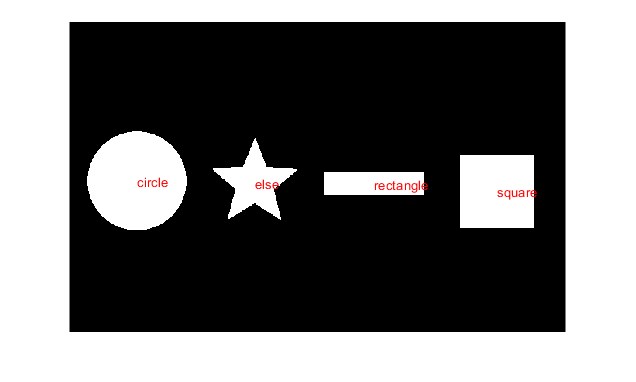

I=(im2bw((rgb2gray(imread("Objects.png"))), 0.5));

imshow(I)
[label,~]=bwlabel(I);
feat=regionprops(label,"all");

for i=1:length(feat)
if (feat(i).BoundingBox(3)*feat(i).BoundingBox(4))==feat(i).Area
feat(i).Shape='rectangle';
if feat(i).BoundingBox(3)==feat(i).BoundingBox(4)
feat(i).Shape='square';
end
elseif feat(i).Circularity>=1
feat(i).Shape='circle';
else
feat(i).Shape='else';
end
text(feat(i).Centroid(1), feat(i).Centroid(2),feat(i).Shape,'Color', 'r')
end

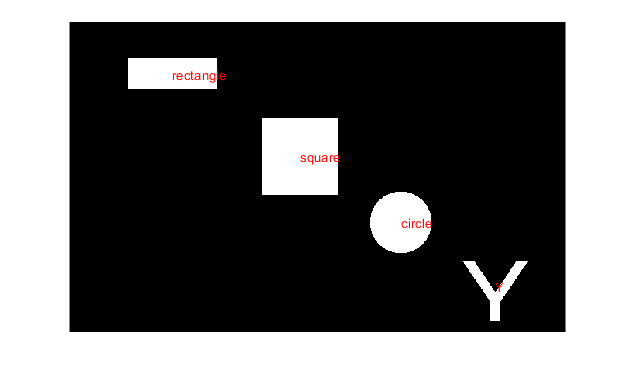

I=1-(im2bw((rgb2gray(imread("Objects2.jpg"))), 0.5));

imshow(I)
[label, num]=bwlabel(I);
feat=regionprops(label,"all");

for i=1:length(feat)
if (feat(i).BoundingBox(3)*feat(i).BoundingBox(4))==feat(i).Area
feat(i).Shape='rectangle';
if feat(i).BoundingBox(3)==feat(i).BoundingBox(4)
feat(i).Shape='square';
end
elseif feat(i).Circularity>=1
feat(i).Shape='circle';
else
feat(i).Shape='Y';
end
text(feat(i).Centroid(1), feat(i).Centroid(2),feat(i).Shape,'Color', 'r')
end

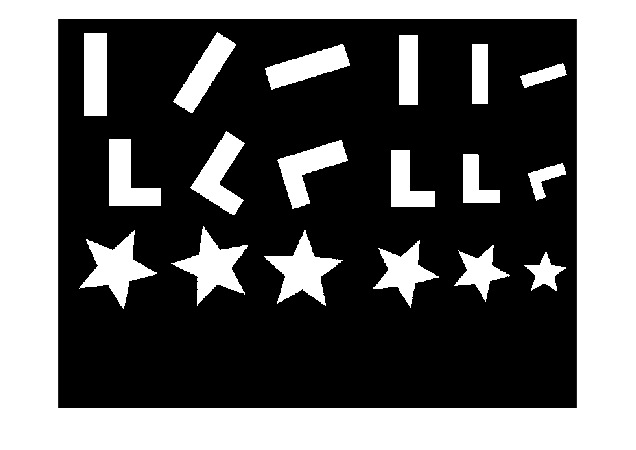

B=1-(im2bw((rgb2gray(imread("ScaleRotation1.jpg"))), 0.5));

imshow(B)

[label, num]=bwlabel(B);
feat=regionprops(label,"all");

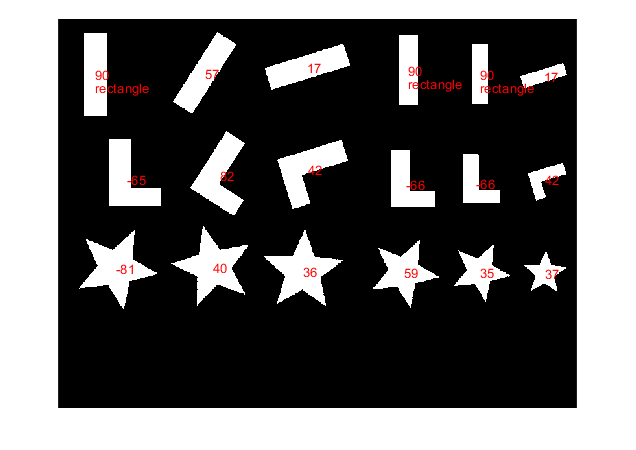


for i=1:num
    if (feat(i).BoundingBox(3)*feat(i).BoundingBox(4))==feat(i).Area
feat(i).Shape='rectangle';
text(feat(i).Centroid(1),feat(i).Centroid(2)+20,(feat(i).Shape),'Color','r')
    end
text(feat(i).Centroid(1),feat(i).Centroid(2),mat2str(round(feat(i).Orientation)),'Color','r')

    
end